clc;
clear;
close all;

%% ========================================================
% STEP 3: SYNTHETIC CAMERA + IMU
%
% INPUT FROM STEP 2:
%   waypoints
%   waypointTime
%   t
%   dt
%   pd
%   vd
%   ad
%
% OUTPUT FOR STEP 4:
%   p_true
%   v_true
%   a_true
%   R_true
%   omega_true
%   p_camera
%   R_camera
%   a_imu
%   omega_imu
% ========================================================

load('drone_toy_model.mat');

%% --------------------------------------------------------
% 1. Use trajectory generated by STEP 2
% ---------------------------------------------------------

numSamples = length(t);

%% --------------------------------------------------------
% 2. True state
% ---------------------------------------------------------

p_true = pd;

v_true = vd;

a_true = ad;

%% --------------------------------------------------------
% 3. Gravity
% ---------------------------------------------------------

g = [0; 0; -9.81];

%% --------------------------------------------------------
% 4. Construct true drone attitude
%
% The drone:
%
%   - points its yaw approximately along velocity
%   - tilts according to horizontal acceleration
%
% R_true maps body-frame vectors into world frame.
% ---------------------------------------------------------

R_true = zeros(3,3,numSamples);

for k = 1:numSamples

    %% Desired yaw

    if norm(v_true(k,1:2)) > 1e-4

        yaw = atan2( ...
            v_true(k,2), ...
            v_true(k,1));

    else

        yaw = 0;

    end

    %% Approximate pitch

    pitch = atan2( ...
        a_true(k,1), ...
        9.81);

    %% Approximate roll

    roll = -atan2( ...
        a_true(k,2), ...
        9.81);

    %% Rotation about X

    Rx = [
        1 0 0;
        0 cos(roll) -sin(roll);
        0 sin(roll) cos(roll)
    ];

    %% Rotation about Y

    Ry = [
        cos(pitch) 0 sin(pitch);
        0 1 0;
        -sin(pitch) 0 cos(pitch)
    ];

    %% Rotation about Z

    Rz = [
        cos(yaw) -sin(yaw) 0;
        sin(yaw) cos(yaw) 0;
        0 0 1
    ];

    %% Body-to-world rotation

    R_true(:,:,k) = ...
        Rz * Ry * Rx;

end

%% --------------------------------------------------------
% 5. Calculate true angular velocity
%
% R_dot = R * skew(omega)
%
% Therefore:
%
% omega approximately comes from:
%
% R_k' * R_(k+1)
% ---------------------------------------------------------

omega_true = zeros(numSamples,3);

for k = 1:numSamples-1

    R_relative = ...
        R_true(:,:,k)' * ...
        R_true(:,:,k+1);

    delta_theta = ...
        logSO3(R_relative);

    omega_true(k,:) = ...
        (delta_theta/dt)';

end

% Hold final angular velocity equal to previous sample

omega_true(end,:) = ...
    omega_true(end-1,:);

%% --------------------------------------------------------
% 6. Sensor parameters
% ---------------------------------------------------------

% Camera position noise

sigma_position = 0.05;          % m

% Camera attitude noise

sigma_camera_angle = ...
    deg2rad(1.0);               % rad

% Accelerometer noise

sigma_acceleration = 0.10;      % m/s^2

% Accelerometer bias

accel_bias = [
    0.02 -0.01 0.03
];

% Gyroscope noise

sigma_gyro = 0.01;              % rad/s

% Gyroscope bias

gyro_bias = [
    0.005 -0.003 0.002
];

%% --------------------------------------------------------
% 7. Camera position measurement
%
% p_camera = p_true + noise
% ---------------------------------------------------------

position_noise = ...
    sigma_position * ...
    randn(numSamples,3);

p_camera = ...
    p_true + position_noise;

%% --------------------------------------------------------
% 8. Camera attitude measurement
%
% R_camera =
% R_true * Exp([noise]x)
% ---------------------------------------------------------

R_camera = ...
    zeros(3,3,numSamples);

camera_angle_noise = ...
    sigma_camera_angle * ...
    randn(numSamples,3);

for k = 1:numSamples

    delta_theta = ...
        camera_angle_noise(k,:)';

    R_camera(:,:,k) = ...
        R_true(:,:,k) * ...
        expm(skew(delta_theta));

    %% Ensure valid SO(3)

    [U,~,V] = svd(R_camera(:,:,k));

    R_camera(:,:,k) = U*V';

    if det(R_camera(:,:,k)) < 0

        U(:,3) = -U(:,3);

        R_camera(:,:,k) = U*V';

    end

end

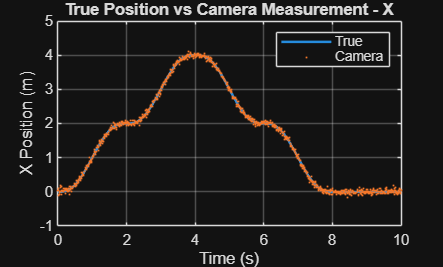


%% --------------------------------------------------------
% 9. IMU acceleration measurement
%
% Accelerometer measures SPECIFIC FORCE:
%
% a_imu =
% R_true' * (a_true - g)
% + b_a
% + n_a
%
% This is the correct body-frame accelerometer model.
% ---------------------------------------------------------

a_imu = zeros(numSamples,3);

for k = 1:numSamples

    Rk = R_true(:,:,k);

    %% Specific force in body frame

    specific_force = ...
        Rk' * ...
        (a_true(k,:)' - g);

    %% Measurement noise

    accel_noise = ...
        sigma_acceleration * ...
        randn(3,1);

    %% Sensor measurement

    a_imu(k,:) = ...
        ( ...
        specific_force ...
        + accel_bias' ...
        + accel_noise ...
        )';

end

%% --------------------------------------------------------
% 10. IMU angular velocity measurement
%
% omega_imu =
% omega_true
% + b_g
% + n_g
% ---------------------------------------------------------

gyro_noise = ...
    sigma_gyro * ...
    randn(numSamples,3);

omega_imu = ...
    omega_true ...
    + repmat(gyro_bias,numSamples,1) ...
    + gyro_noise;

%% --------------------------------------------------------
% 11. Camera position plot
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    p_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    p_camera(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('X Position (m)');

title('True Position vs Camera Measurement - X');

legend( ...
    'True', ...
    'Camera');

grid on;

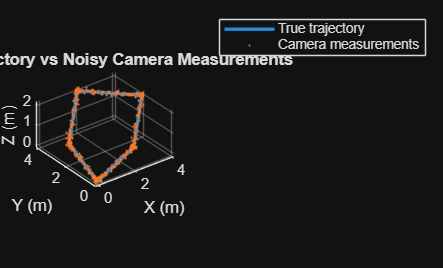


%% --------------------------------------------------------
% 12. 3D camera measurement
% ---------------------------------------------------------

figure;

plot3( ...
    p_true(:,1), ...
    p_true(:,2), ...
    p_true(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    p_camera(:,1), ...
    p_camera(:,2), ...
    p_camera(:,3), ...
    '.', ...
    'MarkerSize',3);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('True Trajectory vs Noisy Camera Measurements');

legend( ...
    'True trajectory', ...
    'Camera measurements');

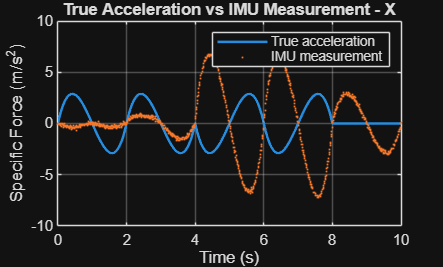


%% --------------------------------------------------------
% 13. IMU acceleration measurement
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    a_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    a_imu(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('Specific Force (m/s^2)');

title('True Acceleration vs IMU Measurement - X');

legend( ...
    'True acceleration', ...
    'IMU measurement');

grid on;

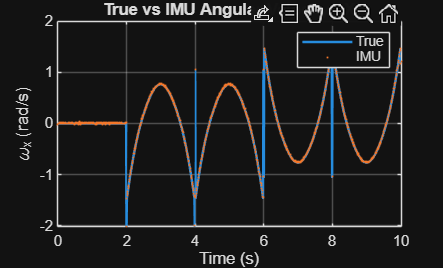


%% --------------------------------------------------------
% 14. Gyroscope measurement
% ---------------------------------------------------------

figure;

plot( ...
    t, ...
    omega_true(:,1), ...
    'LineWidth',1.5);

hold on;

plot( ...
    t, ...
    omega_imu(:,1), ...
    '.', ...
    'MarkerSize',3);

xlabel('Time (s)');
ylabel('\omega_x (rad/s)');

title('True vs IMU Angular Velocity - X');

legend( ...
    'True', ...
    'IMU');

grid on;


%% --------------------------------------------------------
% 15. Sensor statistics
% ---------------------------------------------------------

position_error = ...
    p_camera - p_true;

fprintf('\n');
fprintf('========================================\n');

fprintf('SYNTHETIC SENSOR RESULTS\n');

SYNTHETIC SENSOR RESULTS


fprintf('========================================\n');


fprintf('\nCamera position noise RMS = %.4f m\n', ...
    sqrt(mean(position_error(:).^2)));


Camera position noise RMS = 0.0501 m



%% Accelerometer noise

accel_bias_matrix = ...
    repmat(accel_bias,numSamples,1);

acceleration_noise_error = ...
    a_imu ...
    - accel_bias_matrix;

for k = 1:numSamples

    specific_force_true = ...
        (R_true(:,:,k)' * ...
        (a_true(k,:)' - g))';

    acceleration_noise_error(k,:) = ...
        a_imu(k,:) ...
        - specific_force_true ...
        - accel_bias;

end

fprintf( ...
    'Accelerometer noise RMS = %.4f m/s^2\n', ...
    sqrt(mean(acceleration_noise_error(:).^2)));

Accelerometer noise RMS = 0.0988 m/s^2



%% Gyroscope noise

gyro_bias_matrix = ...
    repmat(gyro_bias,numSamples,1);

gyro_noise_error = ...
    omega_imu ...
    - omega_true ...
    - gyro_bias_matrix;

fprintf( ...
    'Gyroscope noise RMS = %.4f rad/s\n', ...
    sqrt(mean(gyro_noise_error(:).^2)));

Gyroscope noise RMS = 0.0096 rad/s


%% --------------------------------------------------------
% 16. Save Step 3 results
% ---------------------------------------------------------

save( ...
    'drone_toy_model.mat', ...
    'waypoints', ...
    'waypointTime', ...
    't', ...
    'dt', ...
    'pd', ...
    'vd', ...
    'ad', ...
    'p_true', ...
    'v_true', ...
    'a_true', ...
    'R_true', ...
    'omega_true', ...
    'p_camera', ...
    'R_camera', ...
    'a_imu', ...
    'omega_imu', ...
    'sigma_position', ...
    'sigma_camera_angle', ...
    'sigma_acceleration', ...
    'sigma_gyro', ...
    'accel_bias', ...
    'gyro_bias');

fprintf('\nStep 3 results saved to drone_toy_model.mat\n');


Step 3 results saved to drone_toy_model.mat



%% ========================================================
% LOCAL FUNCTIONS
% =========================================================

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = logSO3(R)

    cos_theta = ...
        (trace(R)-1)/2;

    cos_theta = ...
        max(-1,min(1,cos_theta));

    theta = ...
        acos(cos_theta);

    if theta < 1e-8

        v = zeros(3,1);

    else

        v = ...
            theta/(2*sin(theta)) * ...
            [
                R(3,2)-R(2,3);
                R(1,3)-R(3,1);
                R(2,1)-R(1,2)
            ];

    end

end

R_camera

R_camera = R_camera(:,:,1) =

    0.9998   -0.0152   -0.0128
    0.0148    0.9995   -0.0271
    0.0132    0.0269    0.9996


R_camera(:,:,2) =

    0.9998    0.0082    0.0192
   -0.0084    0.9999    0.0107
   -0.0191   -0.0109    0.9998


R_camera(:,:,3) =

    0.9975   -0.0266    0.0661
    0.0258    0.9996    0.0127
   -0.0664   -0.0109    0.9977


R_camera(:,:,4) =

    0.9995    0.0101    0.0286
   -0.0108    0.9996    0.0249
   -0.0284   -0.0252    0.9993


R_camera(:,:,5) =

    0.9958    0.0102    0.0914
   -0.0104    0.9999    0.0017
   -0.0913   -0.0027    0.9958


R_camera(:,:,6) =

    0.9980    0.0108    0.0625
   -0.0110    0.9999    0.0018
   -0.0625   -0.0025    0.9980


R_camera(:,:,7) =

    0.9974   -0.0066    0.0720
    0.0062    1.0000    0.0056
   -0.0720   -0.0051    0.9974


R_camera(:,:,8) =

    0.9941   -0.0241    0.1060
    0.0227    0.9996    0.0148
   -0.1063   -0.0123    0.9943


R_camera(:,:,9) =

    0.9928   -0.0096    0.1196
    0.0062    0.9996    0.0

open("drone_toy_model.mat")

ans = struct with fields:
              R_camera: [3×3×1001 double]
                R_true: [3×3×1001 double]
                 a_imu: [1001×3 double]
                a_true: [1001×3 double]
            accel_bias: [0.0200 -0.0100 0.0300]
                    ad: [1001×3 double]
                    dt: 0.0100
             gyro_bias: [0.0050 -0.0030 0.0020]
             omega_imu: [1001×3 double]
            omega_true: [1001×3 double]
              p_camera: [1001×3 double]
                p_true: [1001×3 double]
                    pd: [1001×3 double]
    sigma_acceleration: 0.1000
    sigma_camera_angle: 0.0175
            sigma_gyro: 0.0100
        sigma_position: 0.0500
                     t: [1001×1 double]
                v_true: [1001×3 double]
                    vd: [1001×3 double]
          waypointTime: [6×1 double]
             waypoints: [6×3 double]
